clc;
clear;
close all;


% % Read Data
Titanic_table = readtable('train.csv');
Titanic_data = (table2cell(Titanic_table));

class = cell2mat(Titanic_data(:,3));
survived = cell2mat(Titanic_data(:,2));
sex = Titanic_data(:,5);
age = cell2mat(Titanic_data(:,6));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Feature Engineering
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Replace NaN values in age by mean age
mean_age = mean(age,'omitnan');
age(isnan(age))= mean_age;

% Discretize age to bins
Age_Categorized = discretize(age, [0 10 25 50 100],'categorical',{'Under 10', '10-25', '25-50', 'Above 50'});


Age_Categorized = grp2idx(Age_Categorized);
sex = grp2idx(sex);
tbl = table(class, sex, Age_Categorized, survived);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Logistic Regression
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

log_model = fitglm(tbl, 'Distribution','binomial');

ypred = predict(log_model,tbl(:,1:end-1));
% to round the probabilities to 0 and 1 i.e.0:not survived, 1:survived
ypred = round(ypred);
Confusion_Matrix = confusionmat(survived,ypred);
Accuracy = trace(Confusion_Matrix)/sum(Confusion_Matrix, 'all')

Accuracy = 0.7834

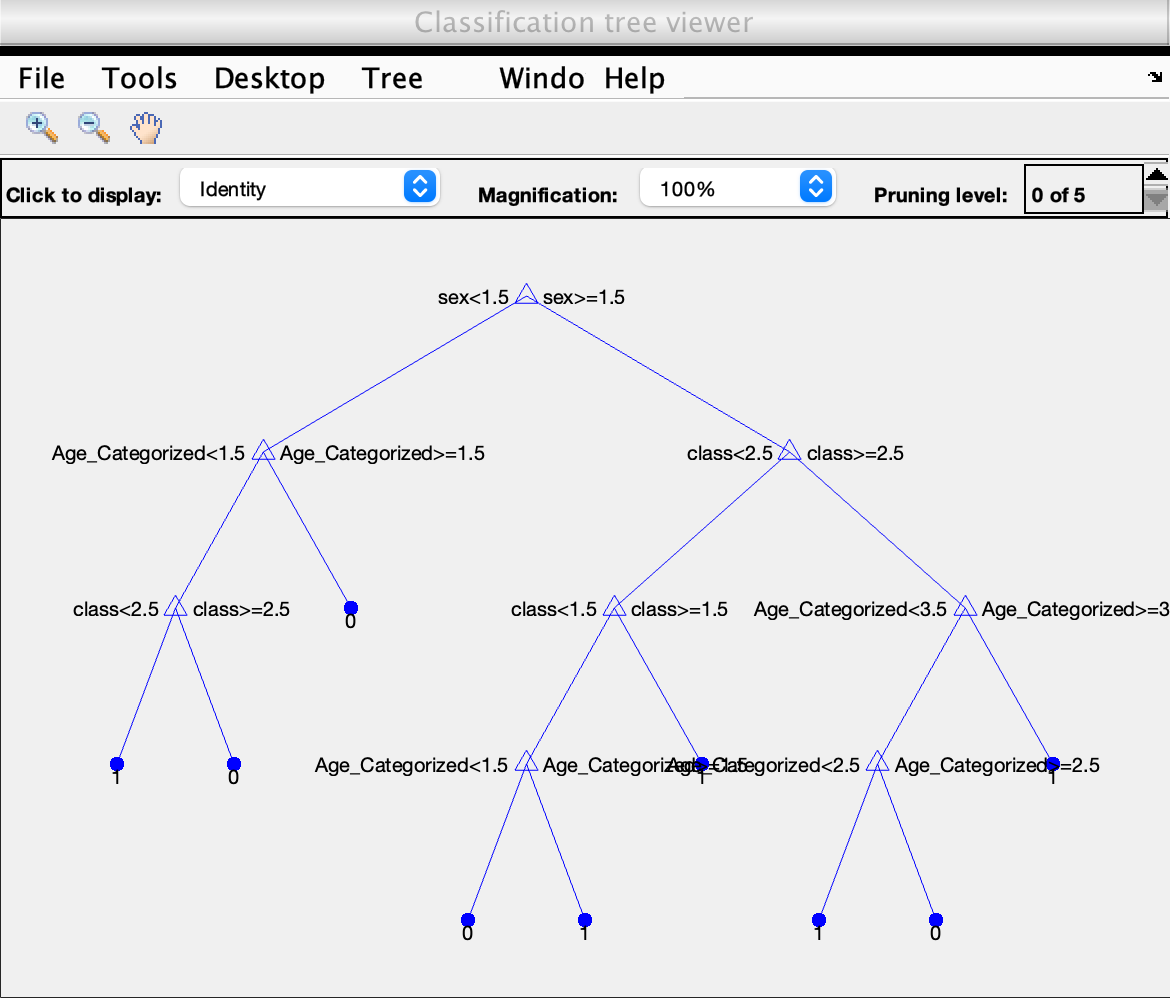

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Fit Decision Tree
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

mytree = fitctree(tbl(:,1:3),tbl(:,4));
% view(mytree, 'Mode', 'graph')

% Pruning the Tree and finding Misclassification error and cross-validation error Best level of pruning
[~,~,~,BestLevel] = cvloss(mytree,'subtrees','all','treesize','min');
prunetree = prune(mytree,'Level',BestLevel);
view(prunetree,'mode','graph')


% Find Accuracy
label = predict(prunetree,tbl(:,1:end-1));
Confusion_Matrix_Tree = confusionmat(survived,label);
Accuracy_Tree = trace(Confusion_Matrix_Tree)/sum(Confusion_Matrix_Tree, 'all')

Accuracy_Tree = 0.8047

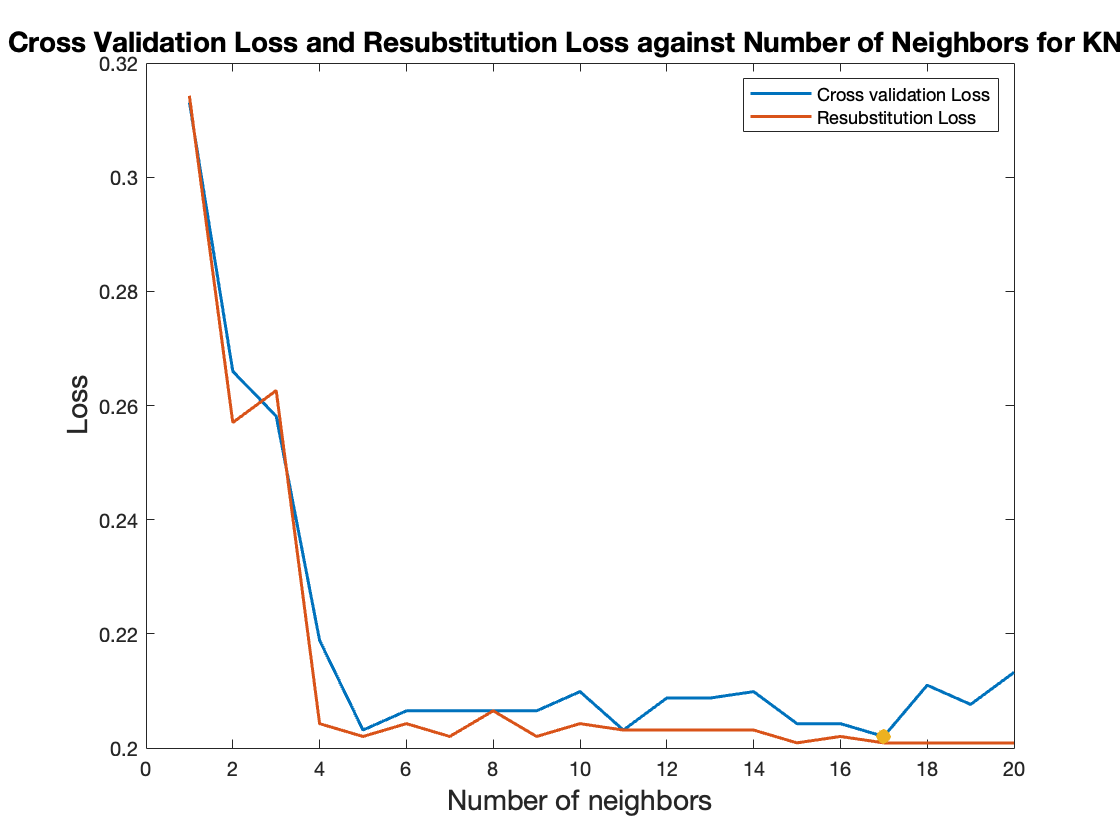

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Fit KNN model
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

knn_model = ClassificationKNN.fit(tbl(:,1:3),tbl(:,4));


% Vary neighbours and find the optimal number of neighbor using Cross validation loss
resub_knn=[];
cv_loss_knn=[];
Neighbors= transpose(1:20);
for num_neighbours = 1:20
rng(1);
knn_model = ClassificationKNN.fit(tbl(:,1:3),tbl(:,4), 'NumNeighbors',num_neighbours);

[r, c] = loss_metrics(knn_model);

resub_knn=[resub_knn;r];
cv_loss_knn=[cv_loss_knn;c];
end

figure('Name', 'KNN')
plot(Neighbors, cv_loss_knn, 'LineWidth',1.5)
hold on;
plot(Neighbors, resub_knn,'LineWidth',1.5)
hold on;
plot(17,cv_loss_knn(17), 'o', 'MarkerFaceColor',[0.9290 0.6940 0.1250], 'LineWidth',1.5)
% hold on;
% plot(13,cv_loss_knn(13), 'o', 'MarkerFaceColor',[0.9290 0.6940 0.1250], 'MarkerEdgeColor',[0.9290 0.6940 0.1250],'LineWidth',1.5)

title('Cross Validation Loss and Resubstitution Loss against Number of Neighbors for KNN ', 'FontSize',14)
xlabel('Number of neighbors', 'FontSize',14)
ylabel('Loss', 'FontSize',14)
legend('Cross validation Loss', 'Resubstitution Loss');




% Fit KNN model with minkowski metric
knn_model_minkowski = ClassificationKNN.fit(tbl(:,1:3),tbl(:,4), 'NumNeighbors',5, 'Distance', 'minkowski');
[resub_loss_knn_minkowski, cv_loss_knn_minkowski] = loss_metrics(knn_model_minkowski);

% Find Accuracy
label_knn = predict(knn_model_minkowski,tbl(:,1:end-1));
Confusion_Matrix_knn = confusionmat(survived,label_knn);
Accuracy_knn = trace(Confusion_Matrix_knn)/sum(Confusion_Matrix_knn, 'all')

Accuracy_knn = 0.7980

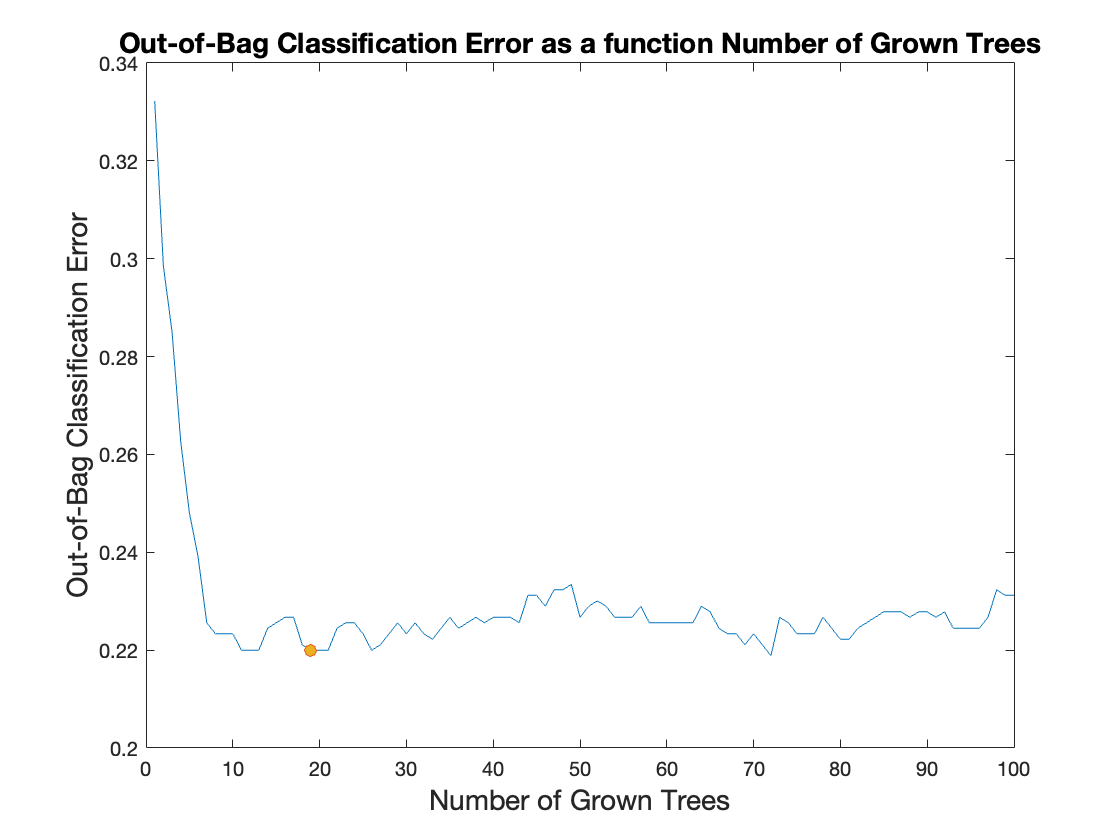

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Fit Random Forest
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

b = TreeBagger(100,tbl(:,1:3),tbl(:,4),'OOBPredictorImportance','On');

figure('Name', 'Question3-Random Forest')
oob = oobError(b);
plot(oob); hold on; 
plot(19,oob(19), 'o', 'MarkerFaceColor',[0.9290 0.6940 0.1250])
xlabel('Number of Grown Trees', 'FontSize',14)
ylabel('Out-of-Bag Classification Error', 'FontSize',14)
title('Out-of-Bag Classification Error as a function Number of Grown Trees', 'FontSize',14)

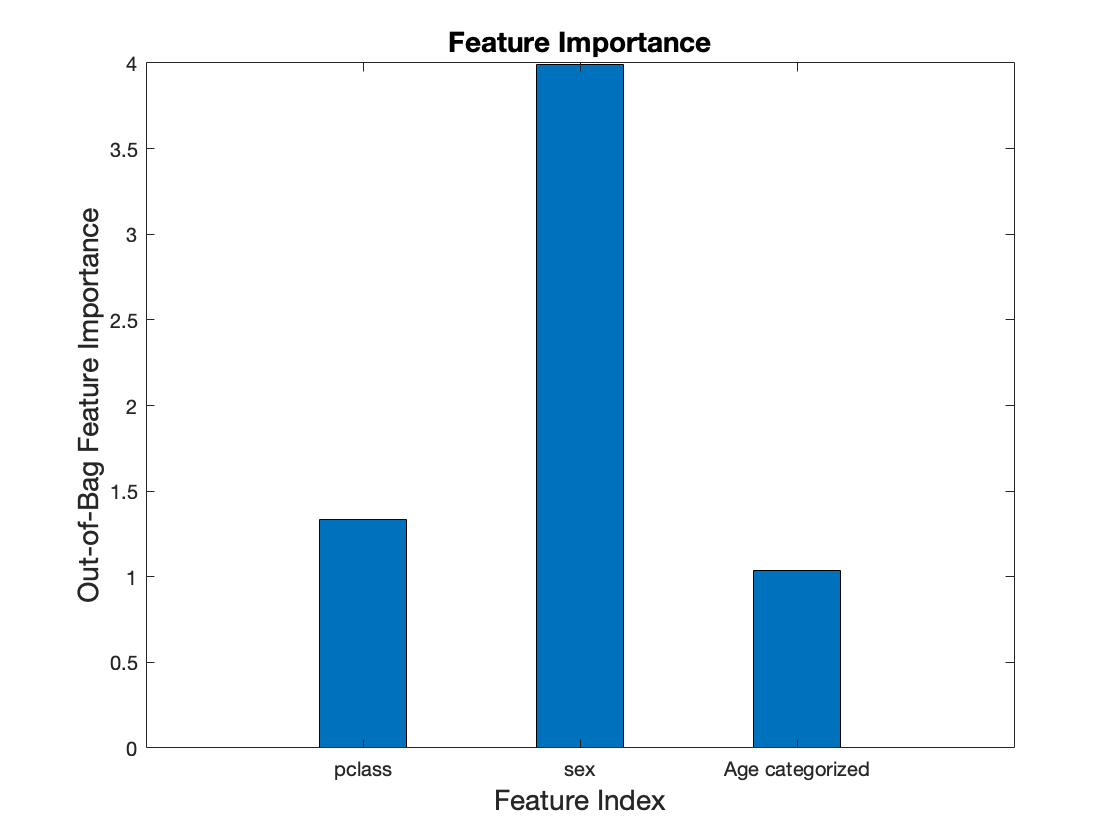


% Estimate feature importance.
figure('Name', 'Question3-Random Forest Feature Importance')
bar(b.OOBPermutedPredictorDeltaError,0.4)
xlabel('Feature Index', 'FontSize',14)
ylabel('Out-of-Bag Feature Importance', 'FontSize',14)
title('Feature Importance', 'FontSize',14)
labels = {'pclass','sex', 'Age categorized'};
xticklabels(labels)




b_optimal = TreeBagger(19,tbl(:,1:3),tbl(:,4),'OOBPredictorImportance','off','OOBPrediction','on');

% Predict
[Yfit,Sfit] = oobPredict(b_optimal);

Confusion_Matrix_RandomForest = confusionmat(survived,str2double(Yfit));
Accuracy_RandomForest = trace(Confusion_Matrix_RandomForest)/sum(Confusion_Matrix_RandomForest, 'all')

Accuracy_RandomForest = 0.7935

%% Prediction on Test Set  


Titanic_table_test = readtable('test.csv');
Titanic_data_test = (table2cell(Titanic_table_test));

PassengerId = cell2mat(Titanic_data_test(:,1)); 
class = cell2mat(Titanic_data_test(:,2));
sex = Titanic_data_test(:,4);
age_test = cell2mat(Titanic_data_test(:,5));

% Replace NaN values in age by mean age
mean_age_test = mean(age_test,'omitnan');
age_test(isnan(age_test))= mean_age_test;

% Discretize age to bins
Age_Categorized = discretize(age_test, [0 10 25 50 100],'categorical',{'Under 10', '10-25', '25-60', 'Above 60'});

Age_Categorized = grp2idx(Age_Categorized);
sex = grp2idx(sex);
tbl_test = table(class, sex, Age_Categorized);



% % Using Logistic Regression Model
% ypred_ = predict(log_model,tbl_test(:,1:end));
% generate_csv(PassengerId, ypred)


% % Using Decision Tree 
% ypred_tree = predict(prunetree,tbl_test(:,1:end));
% generate_csv(PassengerId, ypred_tree)
    
% % Using KNN
% ypred_knn = predict(knn_model_minkowski,tbl_test(:,1:end));
% generate_csv(PassengerId, ypred_knn)


% % % Using RF
 ypred_RF = predict(b_optimal,tbl_test(:,1:end));
 generate_csv(PassengerId, str2double(ypred_RF))






%% Functions

%{
Generate prediction csv
%}

function generate_csv(PassengerId, predicted_labels)

% to round the probabilities to 0 and 1 i.e.0:not survived, 1:survived
Survived = round(predicted_labels);

out = table(PassengerId, Survived);
writetable(out,'predictions_till.csv')

end


% Find Resubstitution loss and Cross validation loss for any model
function [resubstitution_loss, cv_loss] = loss_metrics(model)
% Misclassification error
resubstitution_loss = resubLoss(model);
% cross-validation evaluation
cvc_model = crossval(model);
cv_loss = kfoldLoss(cvc_model);
end